# Haar Transforms for Seismic Data

First, visualize the Haar wavelet.

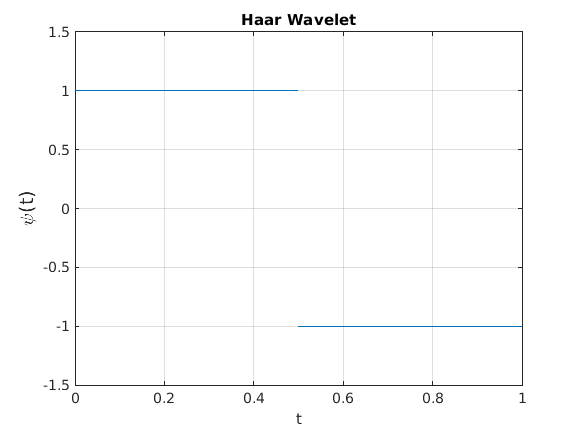

[~,psi,x] = wavefun('haar',10);
x = x(2:end-1);
psi = psi(2:end-1);
hl = plot(x(1:512),psi(1:512));
grid on
hold on
line(x(513:end),psi(513:end))
xlabel('t')
ylabel('\psi(t)','fontsize',14)
title('Haar Wavelet')

# Simulation Of Ground Acceleration Record

Time series of acceleration records are simulated using a stationary process that is "weighted" by an envelope function. The function that fulfils this procedure is 'seismSim'. The parameters of the simulated seismic record are retrieved using the function 'fitKT'

## Ground acceleration record computation

%frequency vector
f = linspace(0,48,4096);
f

f =          0    0.0117    0.0234    0.0352    0.0469    0.0586    0.0703    0.0821    0.0938    0.1055    0.1172    0.1289    0.1407    0.1524    0.1641    0.1758    0.1875    0.1993    0.2110    0.2227    0.2344    0.2462    0.2579    0.2696    0.2813    0.2930    0.3048    0.3165    0.3282    0.3399    0.3516    0.3634    0.3751    0.3868    0.3985    0.4103    0.4220    0.4337    0.4454    0.4571    0.4689    0.4806    0.4923    0.5040    0.5158    0.5275    0.5392    0.5509    0.5626    0.5744


- select `bandwidth of the earthquake excitation`

zeta = 0.3;

- select the standard deviation of `earthquake excitation`

sigma = 0.35;

- select `dominant frequency of the earthquake excitation (Hz).`

fn = 10;

- select `value of the envelop function at 90 percent of the duration.`

T90 = 0.25;

- select `normalized duration time when ground motion achieves peak.`

eps = 0.4;

- **select **duration of ground motion;

tn = 60;

Calling this function

% function call
[y,t] = seismSim(sigma,fn,zeta,f,T90,eps,tn); 
% y: acceleration record
% t: time

### Plot Function

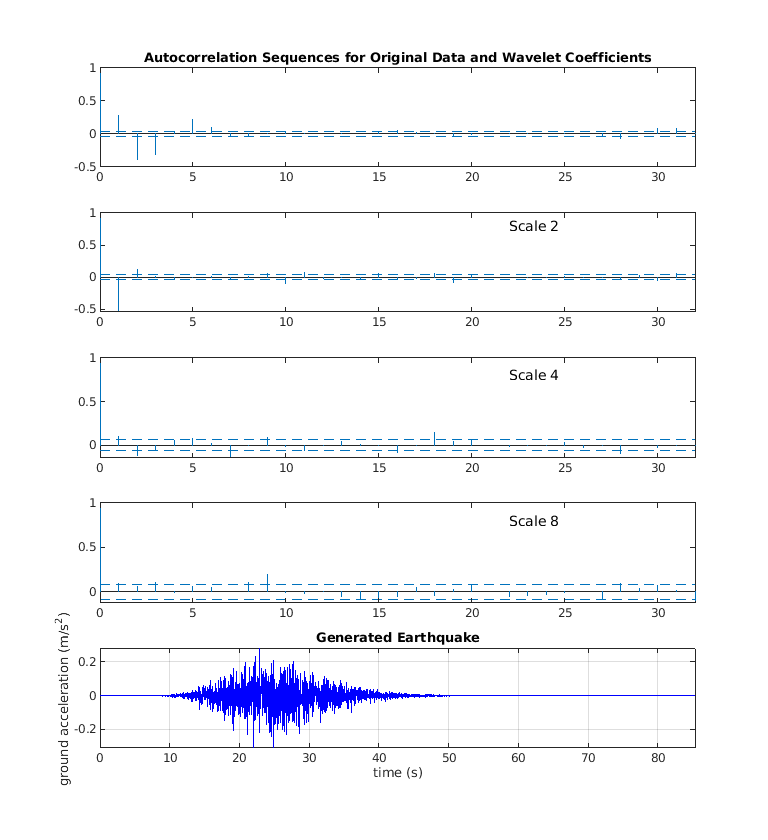

plot(t,y,'b');
xlabel('time (s)')
ylabel('ground acceleration (m/s^2)')
axis tight
grid on;
title('Generated Earthquake');

The Haar transform is useful here because it possesses two important properties: It decorrelates data by scale and it partitions signal energy among scale.To illustrate the decorrelating property, obtain the Haar transform down to level 6. Plot the autocorrelation sequence of the original data along with the autocorrelation of the wavelet coefficients by scale for scales of 2,4,8,16, and 32 time unit. Dashed lines on the plots delineate 95% confidence intervals for white noise inputs. Values exceeding those lines are indicative of significant autocorrelation in the data.

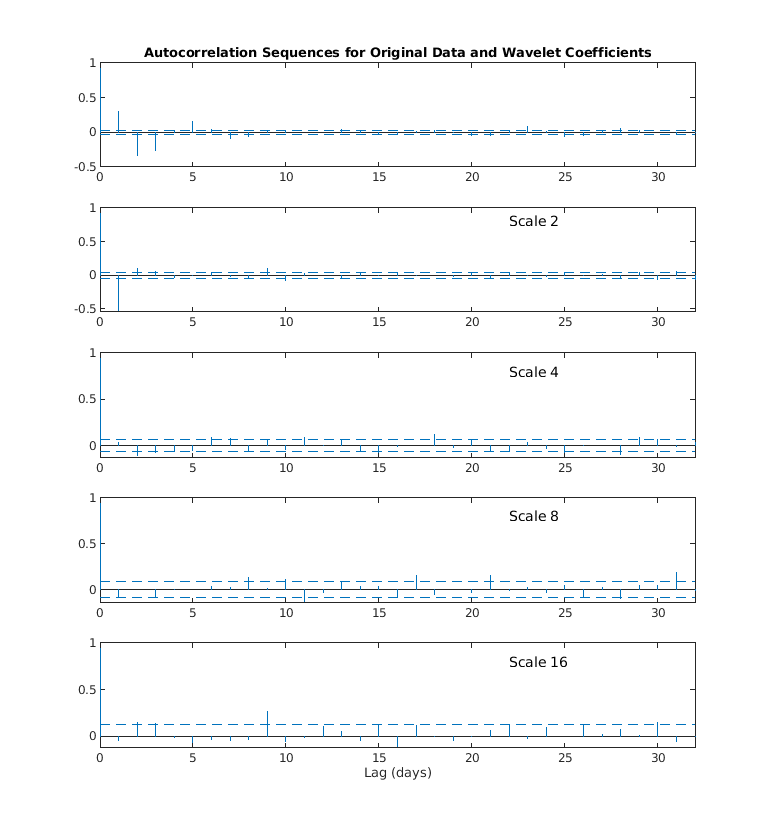

[s,w] = haart(y,6);
helperAutoCorr(y,w);

The top plot shows the autocorrelation sequence for the original data. Subsequent plots show the autocorrelation sequences for wavelet coefficients at increasingly coarser scales. It is clear that the autocorrelation sequence of the original data exhibits correlation at all lags while the Haar transform coefficients are decorrelated. Next, demonstrate energy conservation.

sigenergy = norm(y,2)^2

sigenergy = 5.7469

energyByScale = cellfun(@(x)norm(x,2)^2,w);
haarenergy = norm(s,2)^2+sum(energyByScale)

haarenergy = 5.7469

The total signal energy is preserved by the Haar transform. Because of these properties, you can make meaningful inferences based on the proportion of signal energy captured by the wavelet coefficients at each scale.

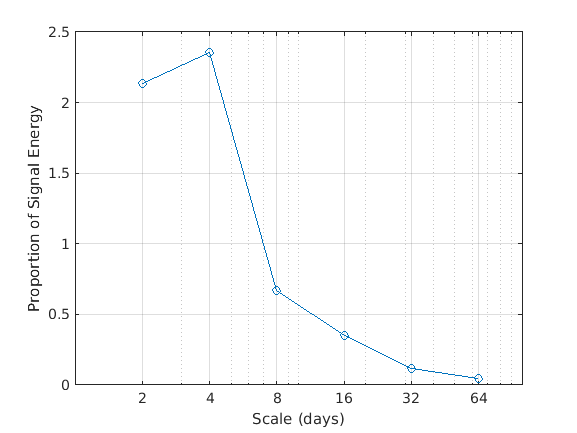

scales = 2.^(1:6);
figure
plot(scales,energyByScale,'-o')
xlabel('Scale time')
set(gca,'xscale','log')
set(gca,'xtick',2.^(1:6))
ylabel('Proportion of Signal Energy')
grid on

#### Simulation Function:

function [y,t] = seismSim(sigma,fn,zeta,f,T90,eps,tn)
% [y,t] = seismSim(sigma,fn,zeta,f,T90,eps,tn) generate one time series
% corresponding to acceleration record from a seismometer. The function
% requires 7 inputs, and gives 2 outputs. The time series is generated in
% two steps: First a stationnary process is created based on the Kanai-
% Tajimi spectrum, then an envelope function is used to transform this 
% stationnary time series into a non-stationary record. For more
% information, see [1-3].
% [1] Lin, Y. K., & Yong, Y. (1987). Evolutionary Kanai-Tajimi earthquake
% models. Journal of engineering mechanics, 113(8), 1119-1137.
% [2] Rofooei, F. R., Mobarake, A., & Ahmadi, G. (2001). 
% Generation of artificial earthquake records with a nonstationary 
% KanaiTajimi model. Engineering Structures, 23(7), 827-837.
% [3] Guo, Y., & Kareem, A. (2016). 
% System identification through nonstationary data using TimeFrequency Blind
% Source Separation. Journal of Sound and Vibration, 371, 110-131.
% 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
% INPUTS 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% sigma: [1 x 1 ]: standard deviation of the excitation.
% fn: [1 x 1 ]: dominant frequency of the earthquake excitation (Hz).
% zeta: [1 x 1 ]:  bandwidth of the earthquake excitation.
% f: [ 1 x M ]: frequency vector for the Kanai-tajimi spectrum.
% T90: [1 x 1 ]: value at 90 percent of the duration.
% eps: [1 x 1 ]: normalized duration time when ground motion achieves peak.
% tn: [1 x 1 ]: duration of ground motion.
% 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
% OUTPUTS 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% y: size: [ 1 x N ] : Simulated aceleration record
% t: size: [ 1 x N ] : time
% 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
% EXAMPLE:
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
% f = linspace(0,40,2048);
% zeta = 0.3;
% sigma = 0.9;
% fn =5;
% T90 = 0.3;
% eps = 0.4;
% tn = 30;
% [y,t] = seismSim(sigma,fn,zeta,f,T90,eps,tn);
% figure
% plot(t,y);axis tight
% xlabel('time(s)');
% ylabel('ground acceleration (m/s^2)')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% see also fitKT.m
% Author: Etienne Cheynet - modified: 23/04/2016

%% Initialisation
w = 2*pi.*f;
fs = f(end); dt = 1/fs;
f0= median(diff(f));
Nfreq = numel(f);
t = 0:dt:dt*(Nfreq-1);

%% Generation of the spectrum S
fn = fn *2*pi; % transformation in rad;
s0 = 2*zeta*sigma.^2./(pi.*fn.*(4*zeta.^2+1));
A = fn.^4+(2*zeta*fn*w).^2;
B = (fn.^2-w.^2).^2+(2*zeta*fn.*w).^2;
S = s0.*A./B; % single sided PSD


%% Time series generation - Monte Carlo simulation
A = sqrt(2.*S.*f0);
B =cos(w'*t + 2*pi.*repmat(rand(Nfreq,1),[1,Nfreq]));
x = A*B; % stationary process

%% Envelop function E
b = -eps.*log(T90)./(1+eps.*(log(T90)-1));
c = b./eps;
a = (exp(1)./eps).^b;
E = a.*(t./tn).^b.*exp(-c.*t./tn);

%% Envelop multiplied with stationary process to get y
y = x.*E;

end

autocorelation